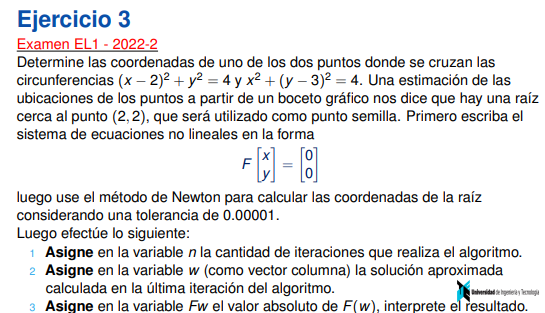

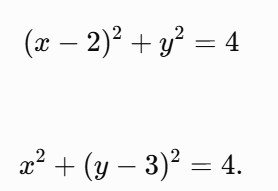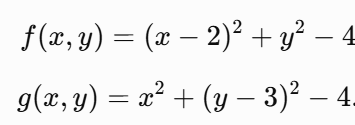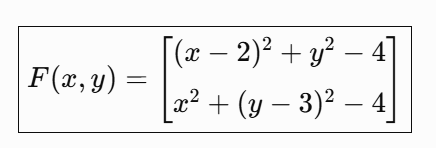


syms x y                                                 % Declara x e y como variables simbólicas

F = @(x,y) [(x-2)^2 + y^2 - 4; ...                       % Define la primera ecuación
    x^2 + (y-3)^2 - 4];                         % Define la segunda ecuación

dF = jacobian(F(x,y),[x y]);                             % Calcula la matriz Jacobiana simbólica

dFfun = matlabFunction(dF,'Vars',{x,y});                 % Convierte la Jacobiana en función numérica

x0 = [2; 2];                                             % Define el punto inicial

Tol = 1e-5;                                              % Define la tolerancia

dr = 1;                                                  % Inicializa el error relativo

i = 0;                                                   % Inicializa el contador de iteraciones

while dr > Tol                                           % Repite mientras no se cumpla la tolerancia

    F_eval = F(x0(1),x0(2));                             % Evalúa F en la aproximación actual

    dFfun_eval = dFfun(x0(1),x0(2));                    % Evalúa la Jacobiana en la aproximación actual

    x1 = x0 - inv(dFfun_eval)*F_eval;                    % Calcula la siguiente aproximación por Newton

    dr = norm(x1-x0,'inf')/norm(x1,'inf');               % Calcula el error relativo

    x0 = x1;                                             % Actualiza la aproximación

    i = i + 1;                                           % Incrementa el número de iteraciones

end                                                      % Finaliza el ciclo

I = i;                                                   % 1. Asigna a I la cantidad de iteraciones realizadas

w = x0;                                                  % 2. Asigna a w la solución aproximada como vector columna

Fw = abs(F(w(1),w(2)));                                  % 3. Asigna a Fw el valor absoluto de F(w)

I                                                       % Muestra la cantidad de iteraciones

I =      4



w                                                       % Muestra la solución aproximada

w =           1.72057669212293
          1.98038446141529



Fw                                                      % Muestra el valor absoluto de F(w)

Fw =       7.72715225139109e-14
      7.63833440942108e-14
